% EE451 Lab 4 notes
% Lisa Jacklin
% 9/22/2023

% slide 24 on lecture 7
% x(z) = 1/((1-0.82^-1)^2(1+0.82^-1))

%we now that the numerator is 1, 
%b = [1];
%and the poles or p, is the bottom half which is a
%a = conv();
%a = conv(a 1 0.8);

%[r, p, k] = 

%this gives the result: 
% X(z) = 0.25/(1 - 0.8z^-1) + 0.5/(1-0.8z^-1) +  0.25/(1+0.8z^-1)
% X(z) = 1/4(1-0.8z^-1) + 1/2(1-0.8z^-1) + 1/4(1+0.8z^-1)

% = [(1/4(1-0.8z^-1)(1+0.8z^-1)) + 1/2(1-0.8z^-1)(1+0.8z^-1) +
% 1/4(1-0.8z^-1)^2]/(1-0.8z^-1)^2(1+0.8z^-1)

%which after some more derivation gives us:

%X(z) = 1/4(1-0.64z^-2)+1/4(1-0.64z^-1) + 1/2(1-1.6z^-1 + 0.64z^-2)

%please note that these values differ here for some reason...reference the
%class code notes for more information on how we should use it...

Lab 4 Begins here!

% for computing large order difference equations, matlab provides filtic to
% use the initial conditions.

%y(n) = 3cos(2*pi*n/5 + 30deg)
%A = 3; NO = 5; phi0= 30; L = 25;
a = [1  1];
b = [3];
y = [ 3*cos(2*pi/5) 3*cos(pi/6)];
xic = filtic(b, a, y);
yzi = filter(b, a, zeros (1, 20), xic);

stem(yzi)


%slide 4 additional problems
%analytically first, then by matlab.
%we are given the initial conditions:
% y(-1) = -2, y(-2) = -3, x(-1) = 1, and x(-2) = 1.

%y(n) = 1/3(x(n) + x(n-1) + x(n-2)) + 0.95y(n-1) + 0.9025y(n-2)

%Y(z) = 1/3[X(z) + x(-1)z^-1X(z) + X(-z)z^-1 + x(-1) + z^-2X(z)]
%       +0.95[y(-1) + z^-1Y(z)] - 0.9025[y(-1)z^-1 + y(-z) + z^-2Y(z)]

%if you get an equation that looks like the above with all the coefficents,
%it will be much easier to plug into Matlab and obtain the answers without
%going about the handwork that is required which is rather extensive...

%after working through this the answer will come out to be:
%Y(z) = [1/3 + 1/3z^-1 + 1/3z^-2]/(1 - 0.952^-1 + 0.9025z^-1)X(z) +
%(1.4742+2.1383z^-1)/(1- 0.952^-1 + 0.90252^-1)

b2 = [1/3 1/3 1/3];
a2 = [1 0.925 0.9025];
y2 = [-2 -3];
x2 = [1 1];

xic2 = filtic(b2, a2, y2, x2)

xic2 =     5.2242    2.1383


y2 = filter(b2,a2,x2,xic2);
stem(y2);

%lab 4 slide 5
%show that e^jwn is periodic in w with period 2pi...
%I am entirely lost on how to do this...


%for w = pi/3, show that e&jwn is periodic in n with period N = 6
w = 0:(2*pi/10):100;
n = 0:1:60;
% WN = n .*w;
% size(WN);
% 
% y = exp(1i.*WN);
% stem(w, y(2,:));


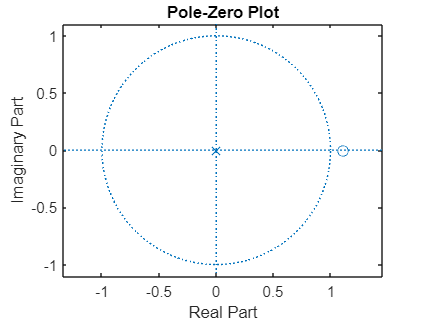

%Lab 4 slide 6 and 7

%y(n) = 0.9y(n-1) + x(n)

%Y(z) = 0.9z^-1Y(z) + X(z)
%Y(z)(1-0.9z^-1) = X(z)

%Y(z)/X(z) = 1/(1-0.9z^-1)

%determine H(z) and sketch its pole-zero plot
a = [-0.9 1];
b = [1];
zplane(a,b);

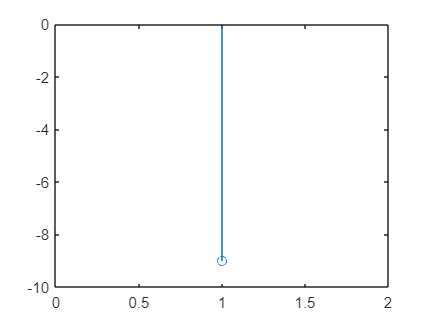



h = 1/(1-(1/0.9));
stem(h)


%b. Plot H(exp(jw)) and phase H(exp(jw))

%c determine the impulse response h(n)

%lab 4 slide 8 (last slide)
%b. determine its difference equation representation and
%c. its impulse response representation.

%H(z) = (z+1) / (z^2 - 0.9z + 0.81) note that this system is causal

%Y(z)/X(z) = (z+1) / (z^2 - 0.9z + 0.81)
        %  = z^-1 + z^-2/ (1 = 0.9z^-1 + 0.81z^-2)
        %note that the move above was done because we know that H(z) is
        %causal
%
%Y(z) - 0.9z^-1Y(z) + 0.81z^02Y(z) = z^-1x(z) + 2^-2X(z)
%y(n) - 0.9y(n-1) _ 0.81y(n-2) = x(n-1)+x(n-2)

%b. difference equation representation
b = [0 1 1]; 
a = [1 -0.9 0.81];
[r, p, k] = residuez(b, a);
abs(r)

ans =     1.1734
    1.1734


%c. impulse resonse representation


